clf
clear
clc
close all 

p.D_p = 7.04*10^-3; %particle diameter (m)
p.bvd = 0.4; % bed voidage 
p.D = 20*10^-3; %tube diameter (m)
p.A = (pi*p.D^2)/4 %cross-sectional area (m2)

p = struct with fields:
    D_p: 0.0070
    bvd: 0.4000
      D: 0.0200
      A: 3.1416e-04


p.P0 = 1.6*10^5 %inlet pressure (Pa)

p = struct with fields:
    D_p: 0.0070
    bvd: 0.4000
      D: 0.0200
      A: 3.1416e-04
     P0: 160000


p.T = 430; %Inlet temperature (K)
p.R = 8.314; %gas constant (J/molK)
p.F_T0 = 100; %inlet total molar flow (mol/s)

%molar mass (kg/mol)
p.MW.CH3OH = 32.04*10^-3;
p.MW.O2 = 32*10^-3;
p.MW.HCHO = 30.03*10^-3;
p.MW.CO = 28.01*10^-3;
p.MW.H2O = 18.02*10^-3;
p.MW.N2 = 28*10^-3;

%inlet mole fraction
p.y_CH3OH_0 = 11/100;
p.y_O2_0 = 6/100;
p.y_HCHO_0 = 0;
p.y_CO_0 = 0;
p.y_H2O_0 = 2/100;
p.y_N2_0 = 81/100;

%initial molar flow rates
p.F0.CH3OH = p.F_T0 * p.y_CH3OH_0;
p.F0.O2 = p.F_T0 * p.y_O2_0;
p.F0.HCHO = p.F_T0 * p.y_HCHO_0;
p.F0.CO = p.F_T0 * p.y_CO_0;
p.F0.H2O = p.F_T0 * p.y_H2O_0;
p.F0.N2 = p.F_T0 * p.y_N2_0; 

p.rho_b = 900 %bed density (kg/m3)

p = struct with fields:
          D_p: 0.0070
          bvd: 0.4000
            D: 0.0200
            A: 3.1416e-04
           P0: 160000
            T: 430
            R: 8.3140
         F_T0: 100
           MW: [1×1 struct]
    y_CH3OH_0: 0.1100
       y_O2_0: 0.0600
     y_HCHO_0: 0
       y_CO_0: 0
      y_H2O_0: 0.0200
       y_N2_0: 0.8100
           F0: [1×1 struct]
        rho_b: 900



p.G = (p.F0.CH3OH*p.MW.CH3OH + p.F0.O2*p.MW.O2 + p.F0.HCHO*p.MW.HCHO ...
        + p.F0.CO*p.MW.CO + p.F0.H2O*p.MW.H2O + p.F0.N2*p.MW.N2)/p.A;

% --- Activation Energy parameters (converted kJ/mol -> J/mol) --- %
    p.A_kCH3OH = 1.50e7;   p.Ea_kCH3OH = 86.00e3;
    p.A_KCH3OH = 2.60e-4;  p.Ea_KCH3OH = -56.78e3;
    p.A_KO2    = 1.42e-5;  p.Ea_KO2    = -60.32e3;
    p.A_KH2O   = 5.50e-7;  p.Ea_KH2O   = -86.45e3;
    p.A_kCO    = 3.50e2;   p.Ea_kCO    = 46.00e3;
    
    % --- Calculation of rate constants from params --- %
    p.kCH3OH = p.A_kCH3OH * exp(-p.Ea_kCH3OH/(p.R*p.T));
    p.KCH3OH = p.A_KCH3OH * exp(-p.Ea_KCH3OH/(p.R*p.T));
    p.KO2    = p.A_KO2    * exp(-p.Ea_KO2/(p.R*p.T));
    p.KH2O   = p.A_KH2O   * exp(-p.Ea_KH2O/(p.R*p.T));
    p.kCO    = p.A_kCO    * exp(-p.Ea_kCO/(p.R*p.T));

p.alpha = 0.4;



function dydz = pbr_odefun(z,y,p)
xi1 = y(1); %extent of reaction 1
xi2 = y(2); %extent of reaction 2
P = y(3); %pressure
%---------------------------------------------
%molar flow rates at z
F_CH3OH = p.F0.CH3OH - xi1;
F_O2 = p.F0.O2 - 0.5*xi1 - 0.5*xi2;
F_HCHO = p.F0.HCHO + xi1 - xi2;
F_CO   = p.F0.CO   + xi2;
F_H2O  = p.F0.H2O  + xi1 + xi2;
F_N2 = p.F0.N2;

if any([F_CH3OH,F_O2,F_HCHO,F_CO,F_H2O,F_N2] < 0) || P <= 0
    dydz = [0;0;0];
    return
end

F_T = F_CH3OH + F_O2 + F_HCHO + F_CO + F_H2O + F_N2;

y_CH3OH = F_CH3OH / F_T;
y_O2   = F_O2   / F_T;
y_HCHO = F_HCHO / F_T;
y_CO   = F_CO   / F_T;
y_H2O  = F_H2O  / F_T;
y_N2= F_N2/ F_T;

P_CH3OH = y_CH3OH * P;
P_O2   = y_O2   * P;
P_HCHO = y_HCHO * P;
P_H2O  = y_H2O  * P;

sqrt_PO2 = sqrt(P_O2);

r1 = p.alpha * (p.kCH3OH * p.KCH3OH * P_CH3OH * p.KO2 * sqrt_PO2) / ...
    ((1 + p.KCH3OH*P_CH3OH + p.KH2O*P_H2O) * (1 + p.KO2*sqrt_PO2));

r2 = p.alpha * (p.kCO * P_HCHO * p.KO2 * sqrt_PO2) / ...
    (1 + p.KO2*sqrt_PO2);

dxi1_dz = r1 * p.rho_b * p.A;
dxi2_dz = r2 * p.rho_b * p.A;

MWmix = y_CH3OH*p.MW.CH3OH + y_O2*p.MW.O2 + y_HCHO*p.MW.HCHO + ...
        y_CO*p.MW.CO + y_H2O*p.MW.H2O + y_N2*p.MW.N2;

rho = (P * MWmix) / (p.R * p.T);

dP_dz = -(1.75 * p.G^2 * (1 - p.bvd)) / (p.D_p * (p.bvd^3) * rho);

dydz = [dxi1_dz; dxi2_dz; dP_dz];

end

zspan = [0 5];
y0 = [0; 0; p.P0]

y0 =            0
           0
      160000


[z, y] = ode45(@(z,y) pbr_odefun(z,y,p), zspan, y0);

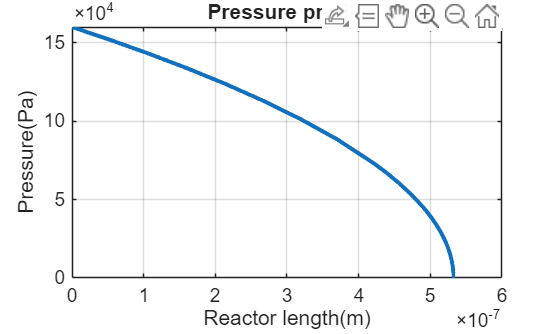


P = y(:,3);

figure("Name","pressure drop along z")
plot(z, P, 'LineWidth', 2)
xlabel('Reactor length(m)')
ylabel('Pressure(Pa)')
title('Pressure profile')
grid on